clear all, close all;

out_floating = sim("float_model.slx")

out_floating =   Simulink.SimulationOutput:

         floating_model: [1x1 struct] 
                   tout: [400001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



FFT_float = out_floating.floating_model.signals(1);
RMS_float = out_floating.floating_model.signals(2);
MIN_float = out_floating.floating_model.signals(3);
MAX_float = out_floating.floating_model.signals(4);

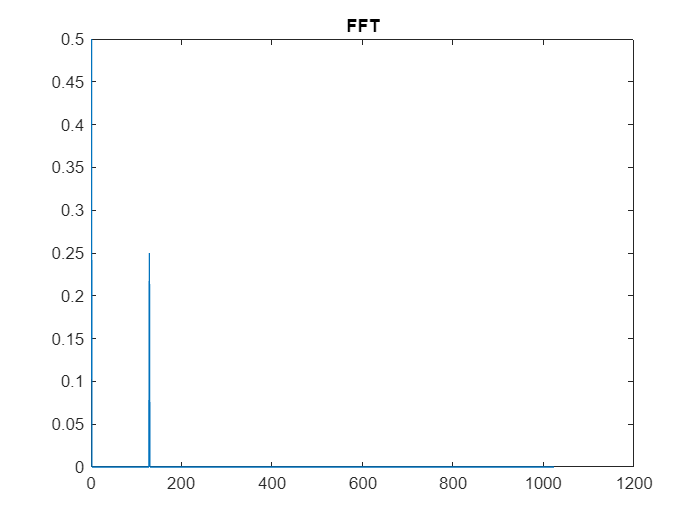

figure;
plot(abs(FFT_float.values(1:1024, 1, 2049)))
title(FFT_float.title)

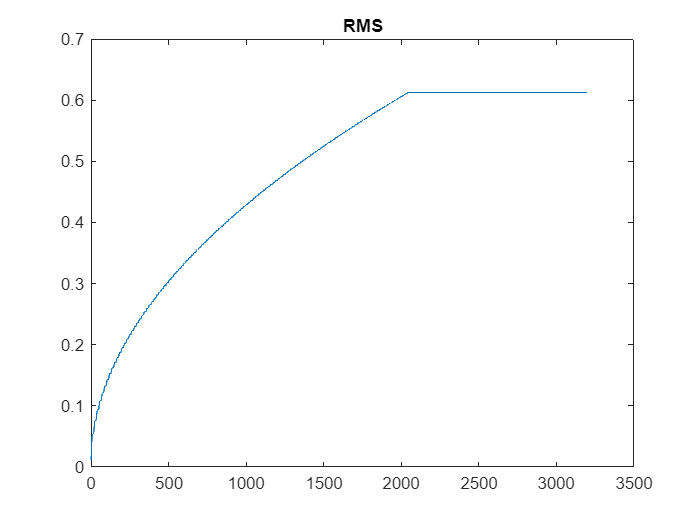


figure;
plot(RMS_float.values(:, :))
title(RMS_float.title)

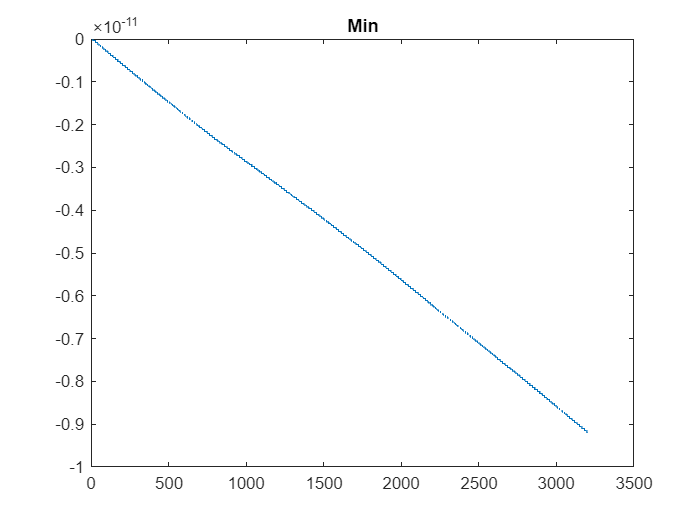


figure;
plot(MIN_float.values(:, :))
title(MIN_float.title)

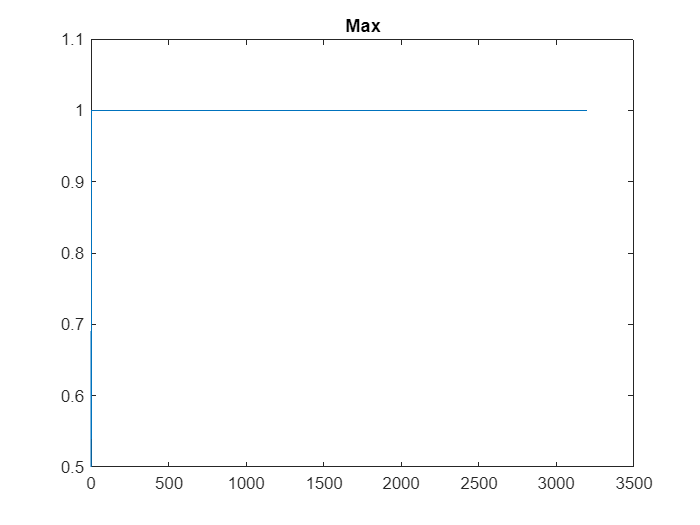


figure;
plot(MAX_float.values(:, :))
title(MAX_float.title)